clc
clear 
close all
% Folder location of the digitized csv files
% Edit the location according to your drivr location where the csv files are saved.
% folder_digit_data="/Users/name/FolderPath";
folder_digit_data="/"; % Current directory

% Simulation data
m_arm_sim= readmatrix(fullfile(folder_digit_data,"m_arm_sim.csv"));
m_sim= readmatrix(fullfile(folder_digit_data,"m_sim.csv"));

% Individual moment arm from different sources
bic_m= readmatrix(fullfile(folder_digit_data,"Bic_m_moment_arm.csv"));
bic_f= readmatrix(fullfile(folder_digit_data,"Bic_f_moment_arm.csv"));
bic_mo= readmatrix(fullfile(folder_digit_data,"Bic_model_moment_arm.csv"));
br_m= readmatrix(fullfile(folder_digit_data,"BRa_m_moment_arm.csv"));
br_f= readmatrix(fullfile(folder_digit_data,"BRa_f_moment_arm.csv"));
br_mo= readmatrix(fullfile(folder_digit_data,"Bra_model_moment_arm.csv"));
brd_m= readmatrix(fullfile(folder_digit_data,"BRD_m_moment_arm.csv"));
brd_f= readmatrix(fullfile(folder_digit_data,"BRd_f_moment_arm.csv"));
brd_mo= readmatrix(fullfile(folder_digit_data,"BRd_model_moment_arm.csv"));

% % Individual Muscle moments.
bic_moment= readmatrix(fullfile(folder_digit_data,"Bicep_moment_adams.csv"));
br_moment= readmatrix(fullfile(folder_digit_data,"Brachialis_moment_adams.csv"));
brd_moment= readmatrix(fullfile(folder_digit_data,"Brachiaoradialis_moment_adams.csv"));

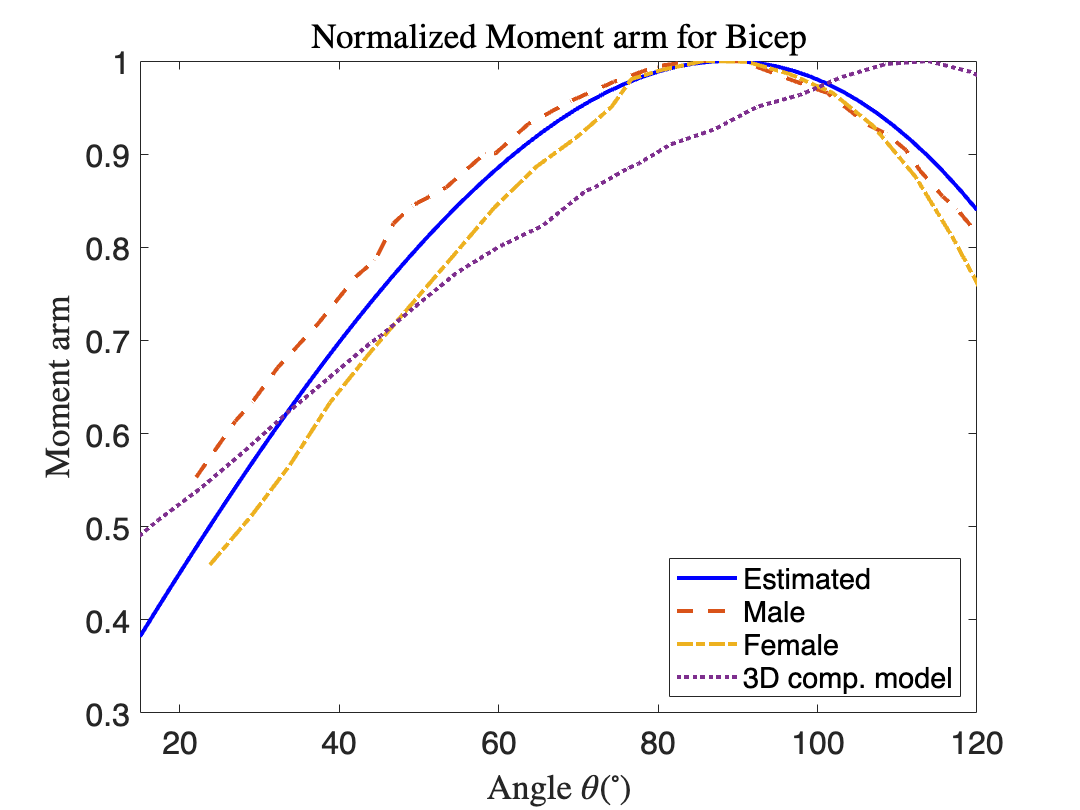

%% Muscle moment arm Comparison Plots

set(0,'defaultTextInterpreter','latex')
% Bicep Muscle moment arm.
plot(m_arm_sim(1,:),m_arm_sim(2,:)/max(m_arm_sim(2,:)),"LineWidth",2,"LineStyle","-",'Color','b')
hold on
plot(bic_m(:,1),bic_m(:,2)/max(bic_m(:,2)),"LineWidth",2,"LineStyle","--")
plot(bic_f(:,1),bic_f(:,2)/max(bic_f(:,2)),"LineWidth",2,"LineStyle","-.")
plot(bic_mo(:,1),bic_mo(:,2)/max(bic_mo(:,2)),"LineWidth",2,"LineStyle",":")
hold off
set(gca,'FontSize',16);
xlim([15 120]);
legend('Estimated','Male','Female','3D comp. model','Location','southeast')
title('Normalized Moment arm for Bicep')
xlabel('Angle $\theta (^\circ)$')
ylabel('Moment arm')

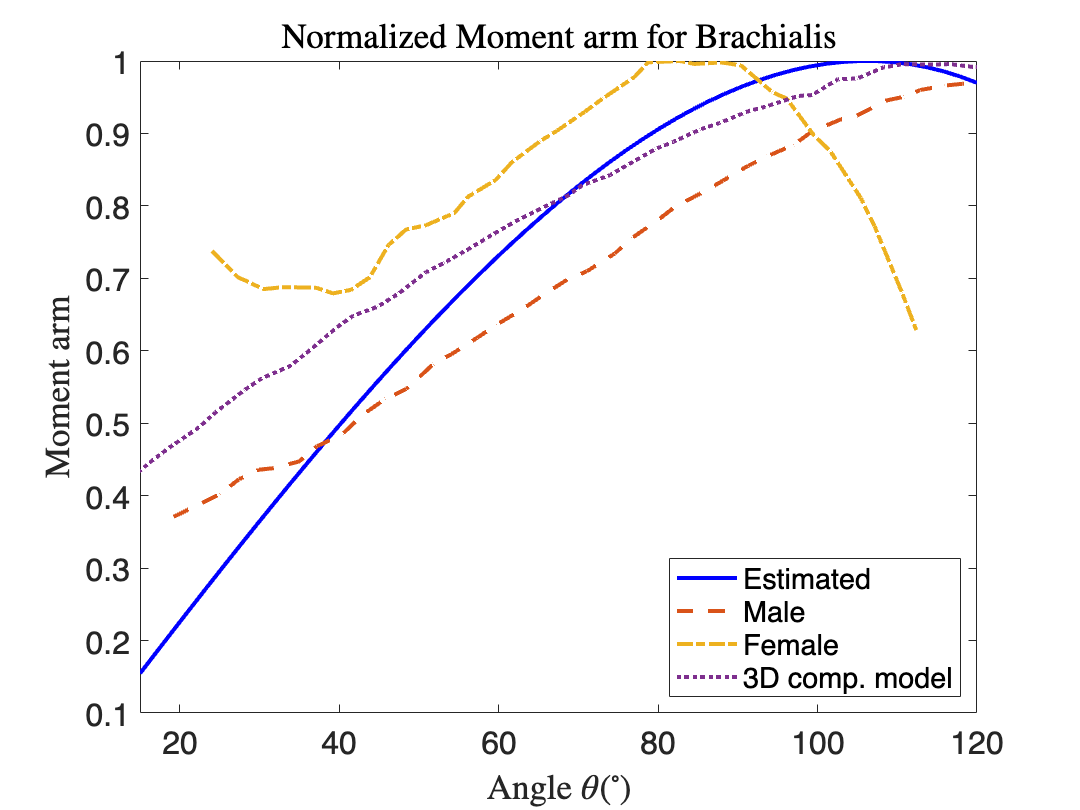


% Brachialis Muscle moemnt arm.
plot(m_arm_sim(1,:),m_arm_sim(3,:)/max(m_arm_sim(3,:)),"LineWidth",2,"LineStyle","-",'Color','b')
hold on
plot(br_m(:,1),br_m(:,2)/max(br_m(:,2)),"LineWidth",2,"LineStyle","--")
plot(br_f(:,1),br_f(:,2)/max(br_f(:,2)),"LineWidth",2,"LineStyle","-.")
plot(br_mo(:,1),br_mo(:,2)/max(br_mo(:,2)),"LineWidth",2,"LineStyle",":")
hold off
set(gca,'FontSize',16);
xlim([15 120]);
legend('Estimated','Male','Female','3D comp. model','Location','southeast')
title('Normalized Moment arm for Brachialis')
xlabel('Angle $\theta (^\circ)$')
ylabel('Moment arm')

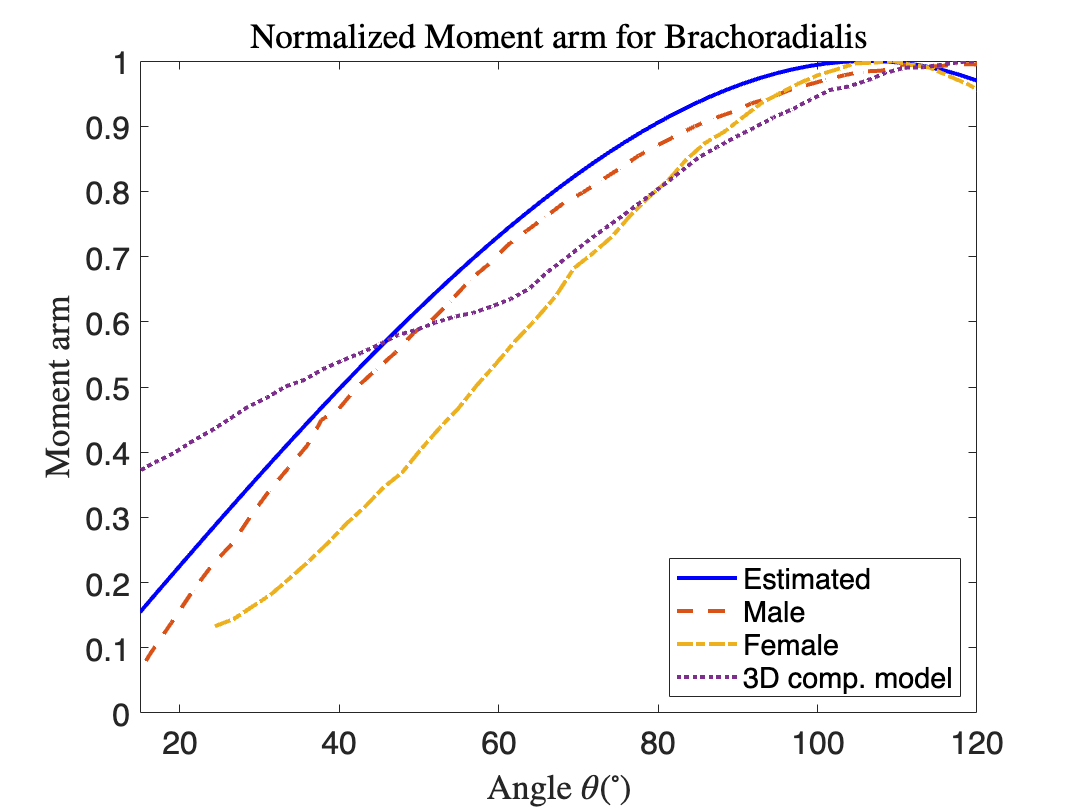


% Brachoradialis muscle moment arm.
plot(m_arm_sim(1,:),m_arm_sim(3,:)/max(m_arm_sim(3,:)),"LineWidth",2,"LineStyle","-",'Color','b')
hold on
plot(brd_m(:,1),brd_m(:,2)/max(brd_m(:,2)),"LineWidth",2,"LineStyle","--")
plot(brd_f(:,1),brd_f(:,2)/max(brd_f(:,2)),"LineWidth",2,"LineStyle","-.")
plot(brd_mo(:,1),brd_mo(:,2)/max(brd_mo(:,2)),"LineWidth",2,"LineStyle",":")
hold off
set(gca,'FontSize',16);
xlim([15 120]);
legend('Estimated','Male','Female','3D comp. model','Location','southeast')
title('Normalized Moment arm for Brachoradialis')
xlabel('Angle $\theta (^\circ)$')
ylabel('Moment arm')

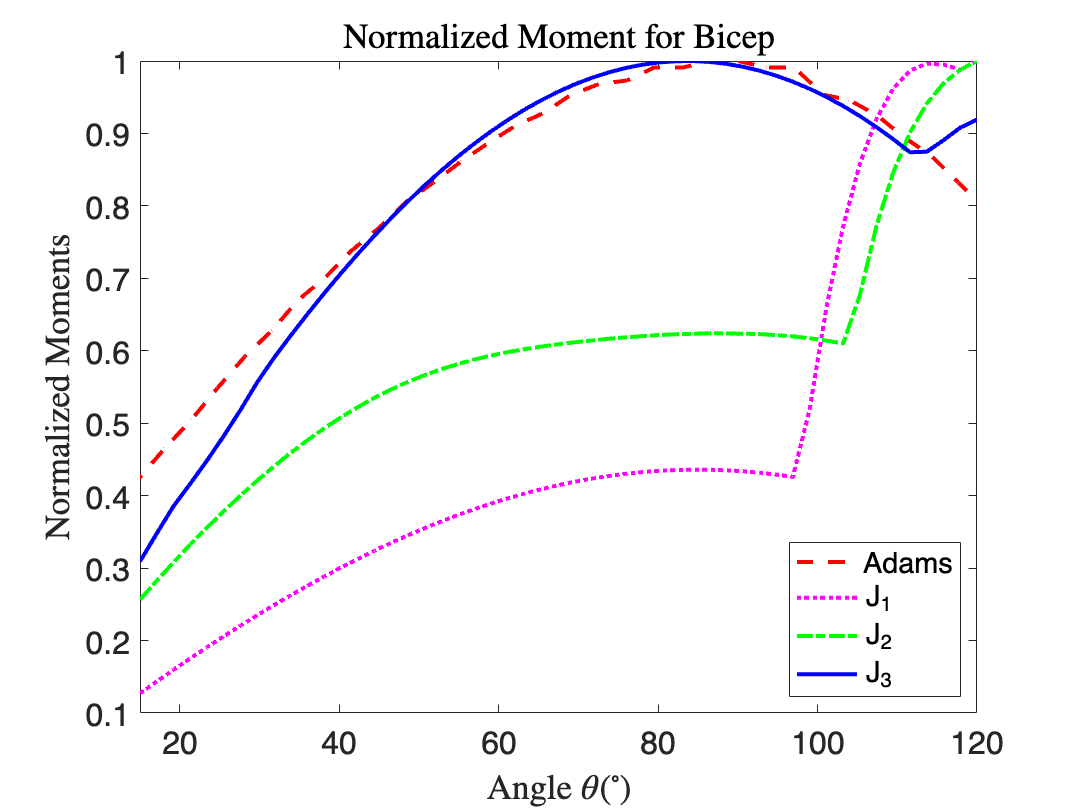

%% Muscle moment Comparison Plots

% Bicep Muscle moment arm.
plot(bic_moment(:,1),bic_moment(:,2)/max(bic_moment(:,2)),"LineWidth",2,"LineStyle","--",'Color','r')
hold on
plot(m_arm_sim(1,:),m_sim(1,:)/max(m_sim(1,:)),"LineWidth",2,"LineStyle",":",'Color','m')
plot(m_arm_sim(1,:),m_sim(4,:)/max(m_sim(4,:)),"LineWidth",2,"LineStyle","-.",'Color','g')
plot(m_arm_sim(1,:),m_sim(7,:)/max(m_sim(7,:)),"LineWidth",2,"LineStyle","-",'Color','b')
hold off
set(gca,'FontSize',16);
xlim([15 120]);
legend('Adams','J_1','J_2','J_3','Location','southeast')
title('Normalized Moment for Bicep')
xlabel('Angle $\theta (^\circ)$')
ylabel('Normalized Moments')

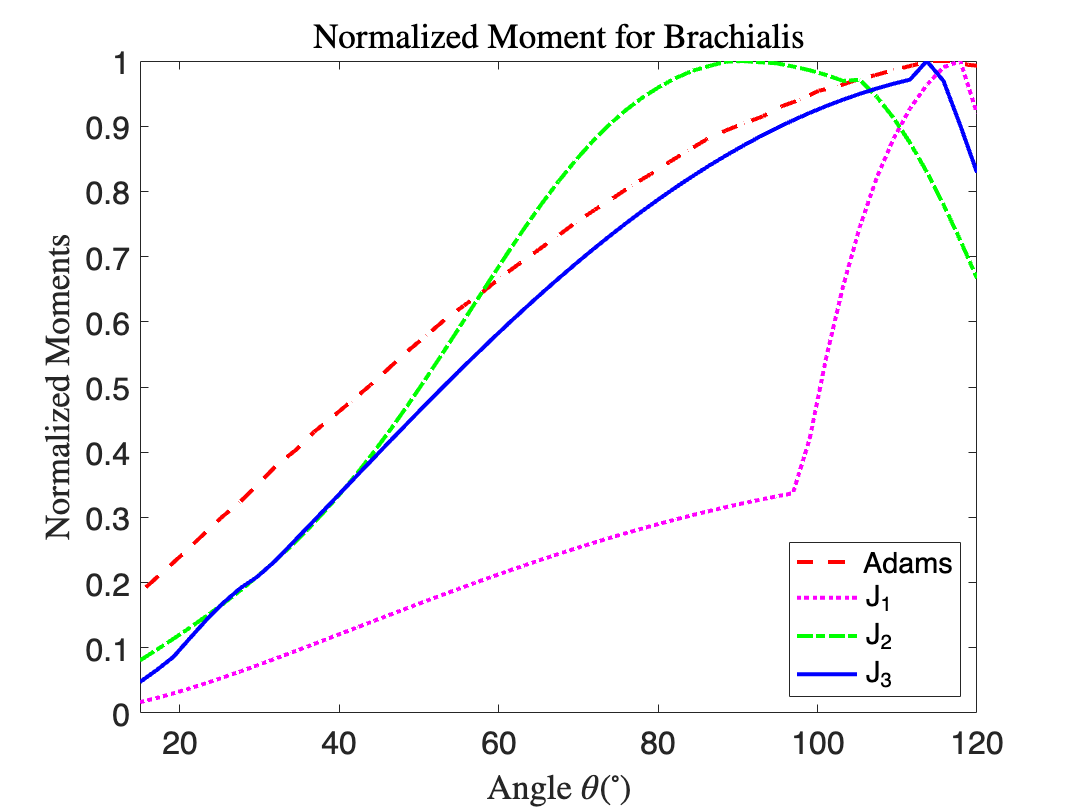


% Brachialis Muscle moemnt arm.
plot(br_moment(:,1),br_moment(:,2)/max(br_moment(:,2)),"LineWidth",2,"LineStyle","--",'Color','r')
hold on
plot(m_arm_sim(1,:),m_sim(2,:)/max(m_sim(2,:)),"LineWidth",2,"LineStyle",":",'Color','m')
plot(m_arm_sim(1,:),m_sim(5,:)/max(m_sim(5,:)),"LineWidth",2,"LineStyle","-.",'Color','g')
plot(m_arm_sim(1,:),m_sim(8,:)/max(m_sim(8,:)),"LineWidth",2,"LineStyle","-",'Color','b')
hold off
set(gca,'FontSize',16);
xlim([15 120]);
legend('Adams','J_1','J_2','J_3','Location','southeast')
title('Normalized Moment for Brachialis')
xlabel('Angle $\theta (^\circ)$')
ylabel('Normalized Moments')

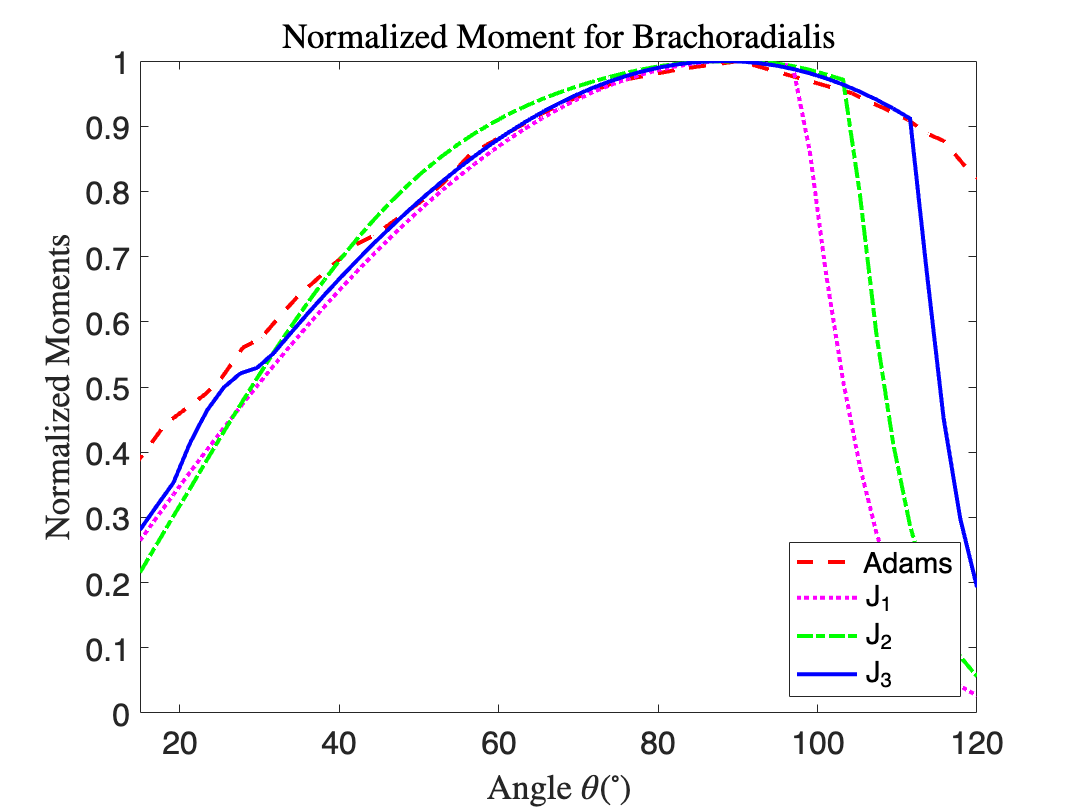


% Brachoradialis muscle moment arm.
plot(brd_moment(:,1),brd_moment(:,2)/max(brd_moment(:,2)),"LineWidth",2,"LineStyle","--",'Color','r')
hold on
plot(m_arm_sim(1,:),m_sim(3,:)/max(m_sim(3,:)),"LineWidth",2,"LineStyle",":",'Color','m')
plot(m_arm_sim(1,:),m_sim(6,:)/max(m_sim(6,:)),"LineWidth",2,"LineStyle","-.",'Color','g')
plot(m_arm_sim(1,:),m_sim(9,:)/max(m_sim(9,:)),"LineWidth",2,"LineStyle","-",'Color','b')
hold off
set(gca,'FontSize',16);
xlim([15 120]);
legend('Adams','J_1','J_2','J_3','Location','southeast')
title('Normalized Moment for Brachoradialis')
xlabel('Angle $\theta (^\circ)$')
ylabel('Normalized Moments')